%% Read the input video

Video = VideoReader('cz1.mp4');
%Video = VideoReader('videoplayback_short.mp4');

% Create object detector for foreground detection 
Object_Detector = vision.ForegroundDetector(...
    'NumTrainingFrames', 36, ...
    'InitialVariance', 30*30);

for i = 1:25
    frame = readFrame(Video);
    Object = step(Object_Detector, frame);
end

Frames

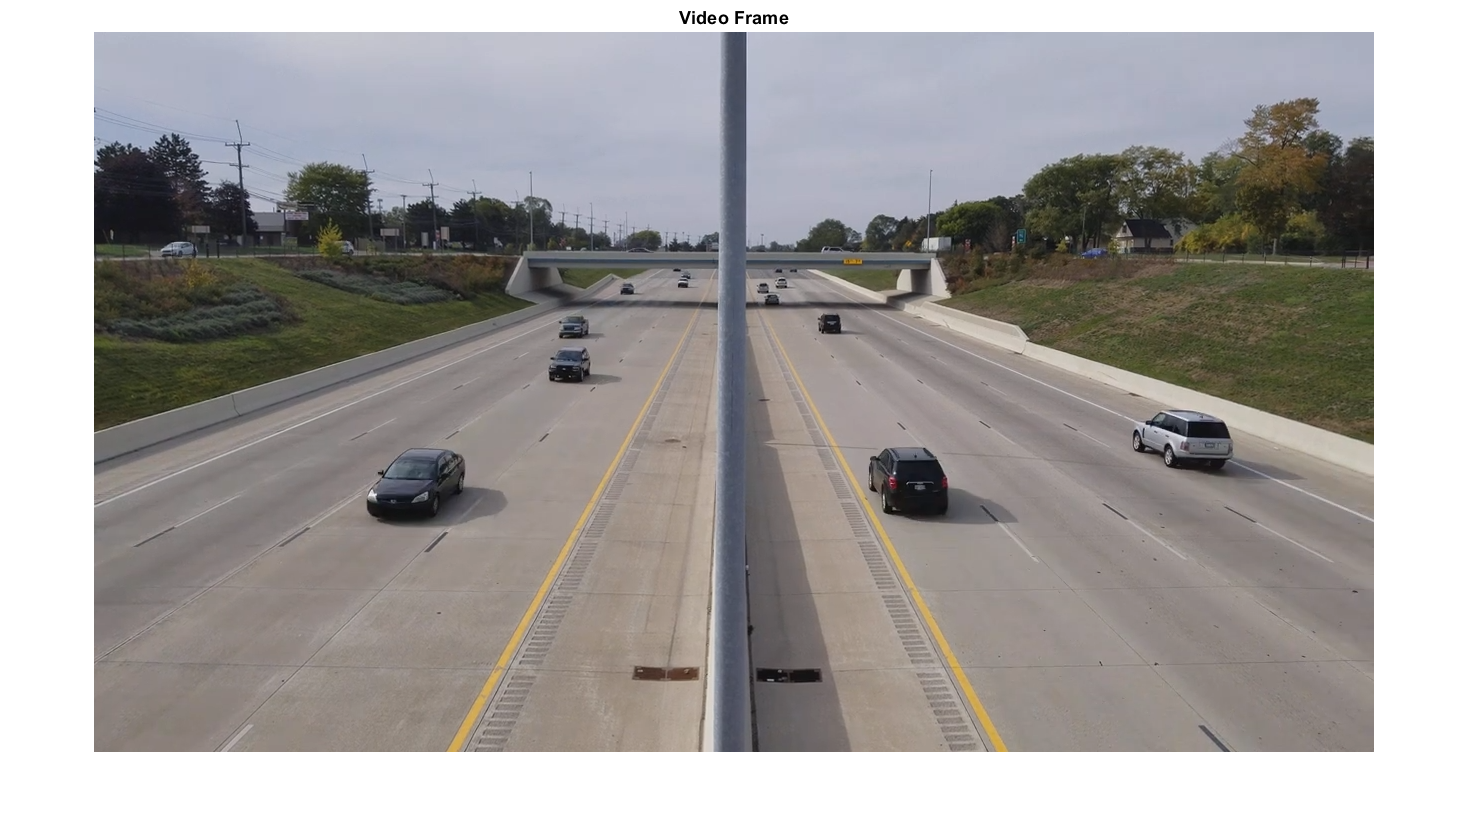

% Show the original video frame
figure; imshow(frame); title('Video Frame');

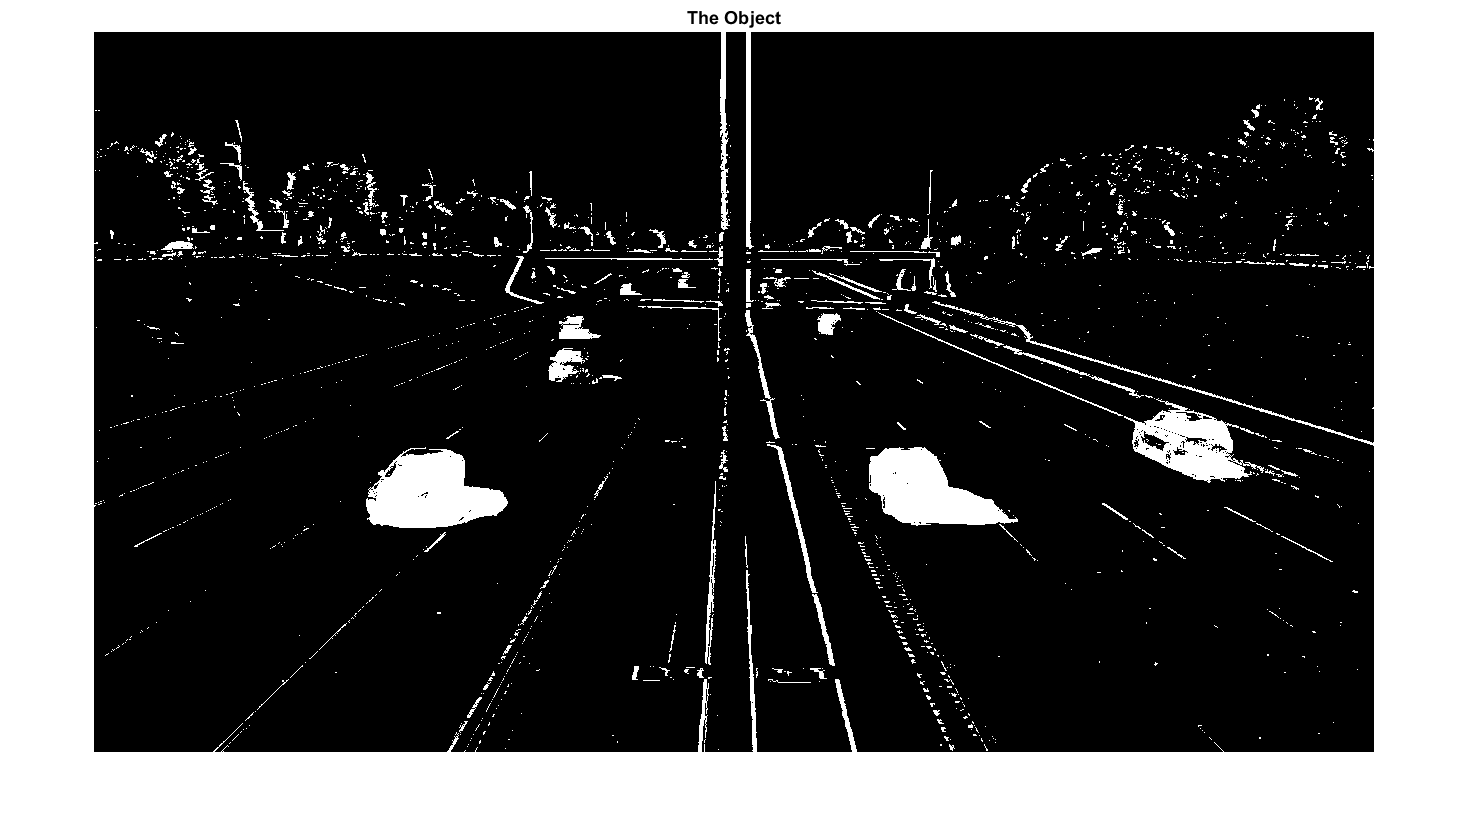


% Show the foreground object
figure; imshow(Object); title('The Object');

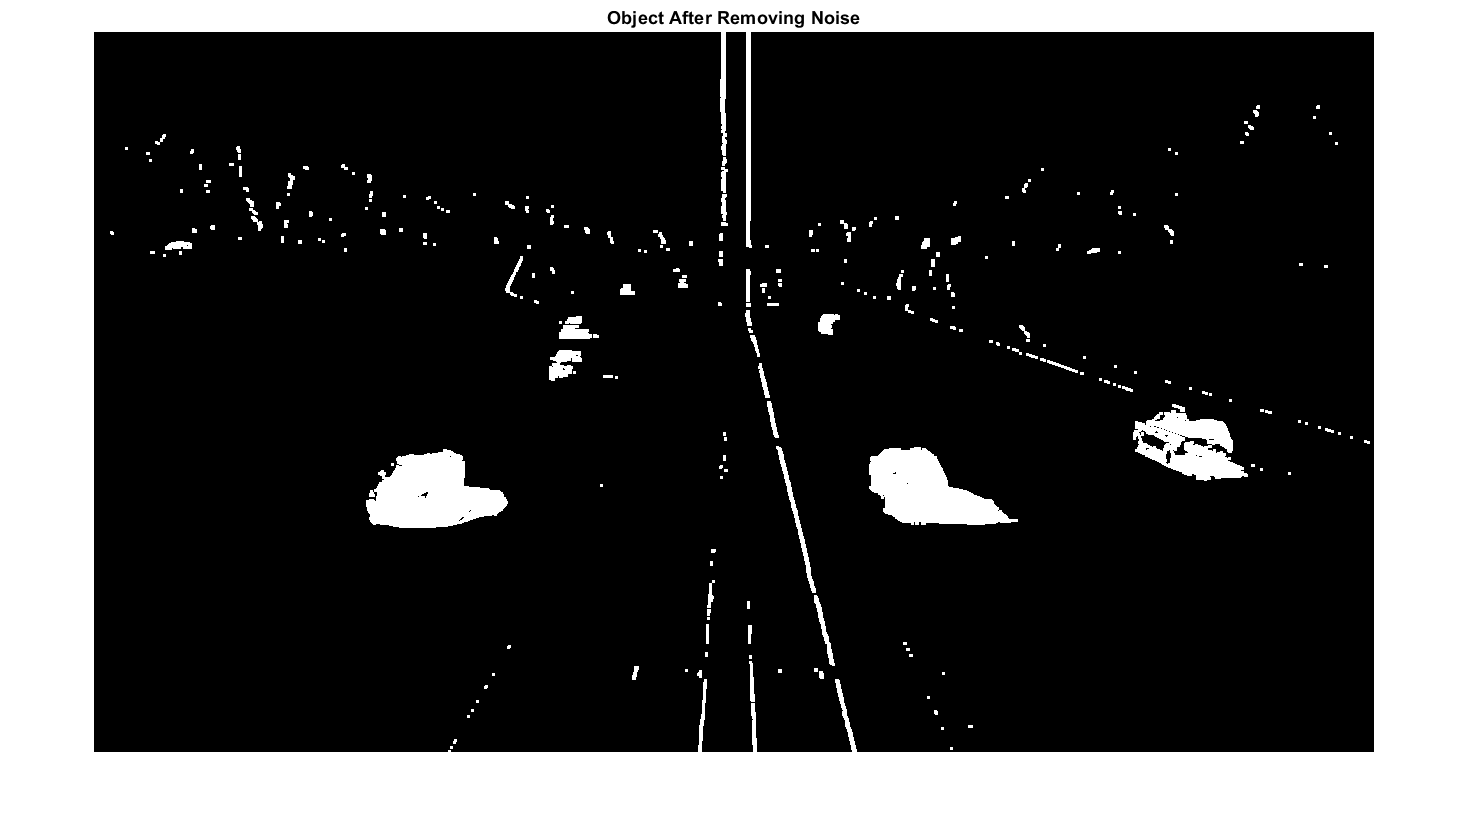


% Perform morphological operation to remove noise
Structure = strel('square', 3);
Noise_Free_Object = imopen(Object, Structure);
figure; imshow(Noise_Free_Object); title('Object After Removing Noise');

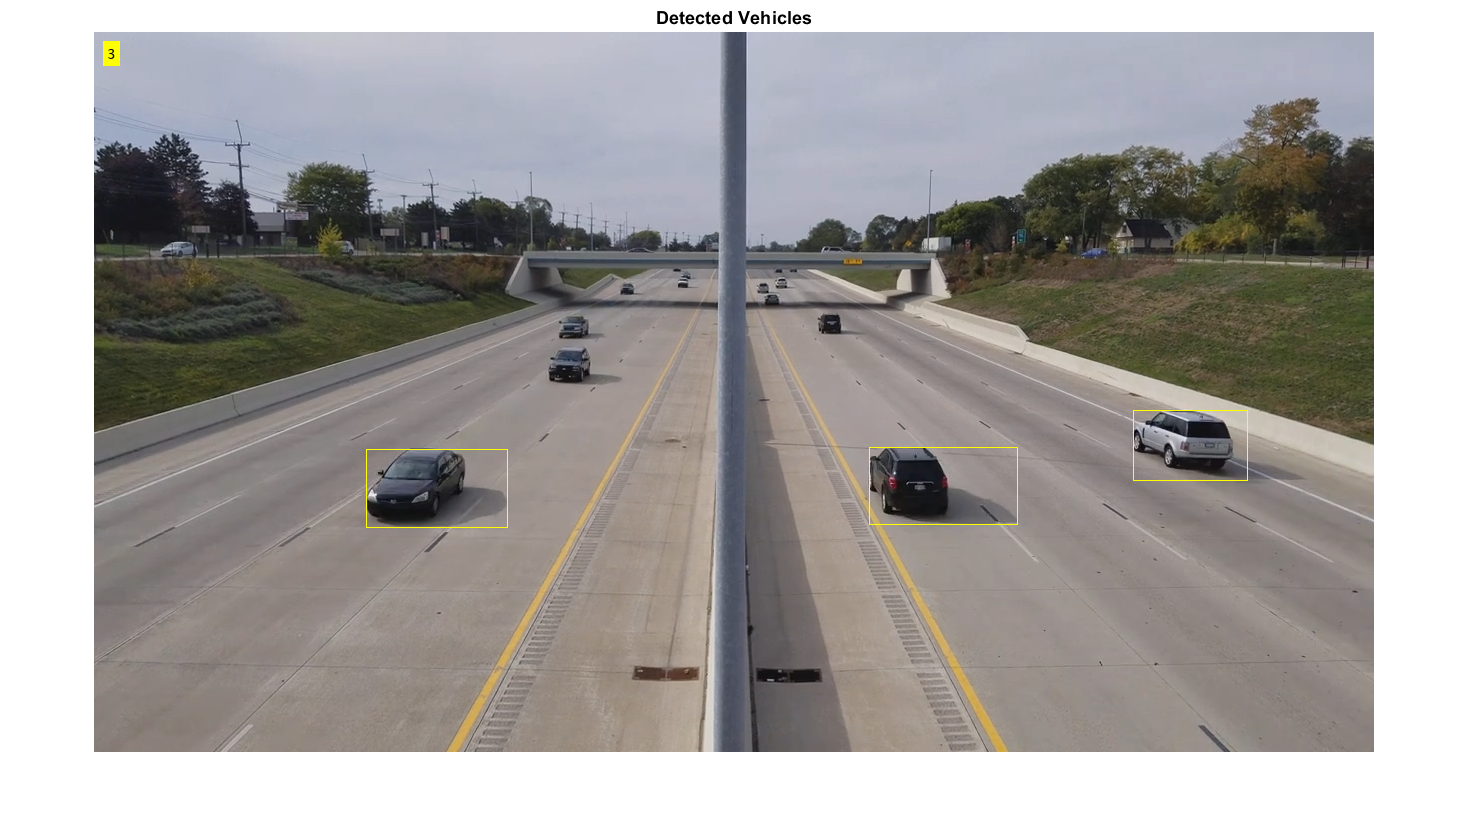


% Locate the object using blob analysis
Bounding_Box = vision.BlobAnalysis('CentroidOutputPort', false, 'AreaOutputPort', false, ...
    'BoundingBoxOutputPort', true, ...
    'MinimumBlobAreaSource', 'Property', 'MinimumBlobArea', 1400);

% Insert the bounding box
The_Box = step(Bounding_Box, Noise_Free_Object);

% Draw the rectangles on the frame
Detected_Vehicle = insertShape(frame, 'Rectangle', The_Box, 'Color', 'yellow');

% Count the number of vehicles
Number_of_Vehicle = size(The_Box, 1);

% Insert text to indicate the number of vehicles
Detected_Vehicle = insertText(Detected_Vehicle, [10 10], Number_of_Vehicle, 'BoxOpacity', 1, 'FontSize', 14);

% Display the detected vehicles
figure; imshow(Detected_Vehicle); title('Detected Vehicles');


% Create a video player
videoPlayer = vision.VideoPlayer('Name', 'Detected Vehicles');
videoPlayer.Position(3:4) = [650, 400];

% Process the remaining frames in the video sequence
while hasFrame(Video)
    frame = readFrame(Video);
    Object = step(Object_Detector, frame);
    Noise_Free_Object = imopen(Object, Structure);
    The_Box = step(Bounding_Box, Noise_Free_Object);
    shapeInserter = vision.ShapeInserter('BorderColor','custom');
    Detected_Vehicle = shapeInserter(frame, The_Box);
    Number_of_Vehicle = size(The_Box, 1);
    Detected_Vehicle = insertText(Detected_Vehicle, [10 10], Number_of_Vehicle, 'BoxOpacity', 1, 'FontSize', 14);
    step(videoPlayer, Detected_Vehicle);
    pause(0.06);
end

